Código para el análisis cinemático del Tripteron mediante cinemática multicuerpo basada en el uso de la ecuación de bucle cerrado (

(CAMBIAR ESTE TÍTULO)

(Recomiendo poner esto fuera del código de matlab, solo en informe)

a: Ubicación del centro u origen para los actuadores.

b: Recorrido de los actuadores.

"c" y "d": Longitud de las barras.

J: Matriz Jacobiana de la máquina.

e: Ubicación del punto de interés con respecto a los pares R de conección en el efector.

q: Vector con las variables cinemáticas.

Fq: Vector con las restricciones Cinemáticas.

P: Matrix with the historic position   ???

V: Matrix with the historic velocities   ???

A: Matrix with the historic acceleration   ???

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear all
clc
close all

%vector desde el sistema de coordenadas hasta el origen de los deslizadores
a1=[0; -300; 0]; a2=[-300; 0; 0]; a3=[-300; -300; 0];

%Longitud de las barras correspondientes a los Brazos
c=150;
d=150;

%driving constraints   ???
px0=-2; vx0=-1; ax0=0;
py0=-3; vy0=-1; ay0=0;
pz0=4; vz0=3; az0=0;

%distancia del punto de interés efector a las articulaciones
e1=[0; 90; 0]; e2=[90; 0; 0]; e3=[90; 90; 0];

%q=[b1 b2 b3 alpha_c alpha_d beta_c beta_d phi_c phi_d px py pz ] Vector de incógnitas 
 q=[-2; -3; 4; deg2rad(47.467); deg2rad(-45.25); deg2rad(42.8); deg2rad(134.99); 0.52; 1; -2.1; -3.2; 4.1 ];


%Solucionador
counter=0;
for t=0:0.1:30
    counter=counter+1;
    res=10;
    iter=1;
    while res>0.00001 && iter<100
        Fq=[a1(1)+q(1)+e1(1)-q(10);
        a1(2)+c*cos(q(4))+d*cos(q(5))+e1(2)-q(11);
        a1(3)+c*sin(q(4))+d*sin(q(5))+e1(3)-q(12);
        a2(1)+c*sin(q(6))+d*sin(q(7))+e2(1)-q(10);
        a2(2)+q(2)+e2(2)-q(11);
        a2(3)+c*cos(q(6))+d*cos(q(7))+e2(3)-q(12);
        a3(1)+c*cos(q(8))+d*cos(q(9))+e3(1)-q(10);
        a3(2)+c*sin(q(8))+d*sin(q(9))+e3(2)-q(11);
        a3(3)+q(3)+e3(3)-q(12);
        q(10)-px0-vx0*t-0.5*ax0*t^2;
        q(11)-py0-vy0*t-0.5*ay0*t^2;
        q(12)-pz0-vz0*t-0.5*az0*t^2;
        ];

        J=[1 0 0 0 0 0 0 0 0 -1 0 0;
           0 0 0 -c*sin(q(4)) -d*sin(q(5)) 0 0 0 0 0 -1 0;
           0 0 0 c*cos(q(4)) d*cos(q(5)) 0 0 0 0 0 0 -1;
           0 0 0 0 0 c*cos(q(6)) d*cos(q(7)) 0 0 -1 0 0;
           0 1 0 0 0 0 0 0 0 0 -1 0;
           0 0 0 0 0 -c*sin(q(6)) -d*sin(q(7)) 0 0 0 0 -1;
           0 0 0 0 0 0 0 -c*sin(q(8)) -d*sin(q(9)) -1 0 0;
           0 0 0 0 0 0 0 c*cos(q(8)) d*cos(q(9)) 0 -1 0;
           0 0 1 0 0 0 0 0 0 0 0 -1;
           0 0 0 0 0 0 0 0 0 1 0 0;
           0 0 0 0 0 0 0 0 0 0 1 0;
           0 0 0 0 0 0 0 0 0 0 0 1;
           ];

        qf = q - J\Fq;
        q = qf;
        res = norm(Fq);
        iter=iter+1;
    end
    if iter>=100
        disp("No convergió...")
    end
    P(:,counter)=qf;

    %Velocidad
    vi=-J\[0; 0; 0; 0; 0; 0; 0; 0; 0; -vx0-ax0*t; -vy0-ay0*t; -vz0-az0*t];
    V(:,counter)=vi;

    %Aceleración
    Jp=[0 0 0 0 0 0 0 0 0 0 0 0;
        0 0 0 -c*vi(4)*cos(q(4)) -d*vi(5)*cos(q(5)) 0 0 0 0 0 0 0;
        0 0 0 -c*vi(4)*sin(q(4)) -d*vi(5)*sin(q(5)) 0 0 0 0 0 0 0;
        0 0 0 0 0 -c*vi(6)*sin(q(6)) -d*vi(7)*sin(q(7)) 0 0 0 0 0;
        0 0 0 0 0 0 0 0 0 0 0 0;
        0 0 0 0 0 -c*vi(6)*cos(q(6)) -d*vi(7)*cos(q(7)) 0 0 0 0 0;
        0 0 0 0 0 0 0 -c*vi(8)*cos(q(8)) -d*vi(9)*cos(q(9)) 0 0 0;
        0 0 0 0 0 0 0 -c*vi(8)*sin(q(8)) -d*vi(9)*sin(q(9)) 0 0 0;
        0 0 0 0 0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0 0 0 0 0;
        ];
    ai=J\(-Jp*vi-[0; 0; 0; 0; 0; 0; 0; 0; 0; -ax0*t; -az0*t; -az0*t]);
    A(:,counter)=ai;
end

Creo que esto sería opcional a partir de aquí (Quitar esto)

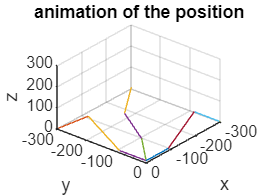

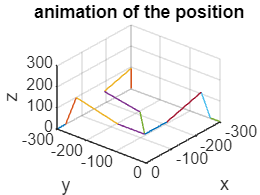

%Animación de la Solución
nSteps=size(P,2);
figure

%pausa
for i=1:nSteps
    O=[0; 0; 0];

    %Brazo_1
    A=a1;
    B=A+[P(1,i);0;0];
    C=B+[0;c*cos(P(4,i));c*sin(P(4,i))];
    D=C+[0;d*cos(P(5,i));d*sin(P(5,i))];
    E=D+e1;
    cla
    plot3([A(1) B(1)],[A(2) B(2)],[A(3) B(3)])
    hold on
    plot3([B(1) C(1)],[B(2) C(2)],[B(3) C(3)])
    plot3([C(1) D(1)],[C(2) D(2)],[C(3) D(3)])
    plot3([D(1) E(1)],[D(2) E(2)],[D(3) E(3)])

    %Brazo_2
    A=a2;
    B=A+[0;P(2,i);0];
    C=B+[c*sin(P(6,i));0;c*cos(P(6,i))];
    D=C+[d*sin(P(7,i));0;d*cos(P(7,i))];
    E=D+e2;
    plot3([A(1) B(1)],[A(2) B(2)],[A(3) B(3)])
    hold on
    plot3([B(1) C(1)],[B(2) C(2)],[B(3) C(3)])
    plot3([C(1) D(1)],[C(2) D(2)],[C(3) D(3)])
    plot3([D(1) E(1)],[D(2) E(2)],[D(3) E(3)])

    %Brazo_3
    A=a3;
    B=A+[0;0;P(3,i)];
    C=B+[c*cos(P(8,i));c*sin(P(8,i));0];
    D=C+[d*cos(P(9,i));d*sin(P(9,i));0];
    E=D+e3;
    plot3([A(1) B(1)],[A(2) B(2)],[A(3) B(3)])
    hold on
    plot3([B(1) C(1)],[B(2) C(2)],[B(3) C(3)])
    plot3([C(1) D(1)],[C(2) D(2)],[C(3) D(3)])
    plot3([D(1) E(1)],[D(2) E(2)],[D(3) E(3)])
    xlabel('x')
    ylabel('y')
    zlabel('z')
    title('animation of the position')
    axis([-300 0 -300 0 0 300])
    view(129.6260,39.6168)
    pause(0.01)
    grid on
end